clear;clc;


## 读入数据并画图

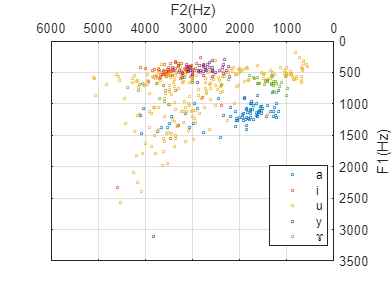

data = readcell('En-3formants-5.8.xlsx'); % 读入散点，n*2矩阵
data(1,:) = []; % 删除表头
emptyInd = cellfun(@ismissing,data(:,6:7));
emptyRow = find(sum(emptyInd,2));
data(emptyRow,:) = []; % 删除空行

dstVowel = unique(data(:,2)); % 筛选获得发各个音的数据
n = length(dstVowel); % 需要拟合的数据组数
plotColour = zeros(n,3); % 每行存储每组数据画图的颜色

% 注意：point每个元胞内的第一列和第二列分别是F1和F2，作图和拟合时F2是x轴F1是y轴
pt = cell(n,1); % 每个元胞内存放一个需拟合的数据组
for k = 1:n
    [ii,~] = find(strcmp(data,dstVowel(k)));
    pt(k) = {cell2mat(data(ii,6:7))};
end

figAll = figure('Name','原始数据');
h = zeros(n,1);
for k = 1:n
    h(k) = plot(pt{k}(:,2),pt{k}(:,1),'o','MarkerSize',2.0);
    plotColour(k,:) = get(h(k),'Color');
    hold on;
end
legend(h,cell2mat(dstVowel),'Location','best');
set(gca,'XDir','reverse'); % 将x轴方向设置为反向(从右到左递增)。
set(gca,'XAxisLocation','top'); % 将x轴的位置设置在顶部。
set(gca,'YDir','reverse'); % 将y轴方向设置为反向(从上到下递增)。
set(gca,'YAxisLocation','right'); % 将y轴的位置设置在右边。
grid on;
xlabel('F2(Hz)');
ylabel('F1(Hz)');

## 置信度95%的椭圆拟合（测试样例）

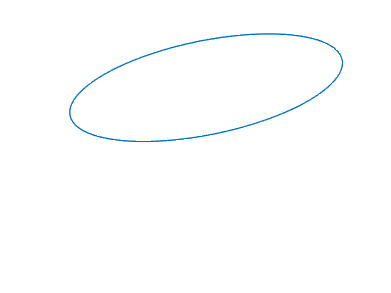

% 以a的发音为例
ptA = pt{1};
figA = figure('Name','a');
% scatter(ptA(:,2),ptA(:,1),4.0);
hold on;
axis([0,4000,0,1600]);

% set(gca,'XDir','reverse'); % 将x轴方向设置为反向(从右到左递增)。
% set(gca,'XAxisLocation','top'); % 将x轴的位置设置在顶部。
% set(gca,'YDir','reverse'); % 将y轴方向设置为反向(从上到下递增)。
% set(gca,'YAxisLocation','right'); % 将y轴的位置设置在右边。
grid off;
% xlabel('F2(Hz)');
% ylabel('F1(Hz)');

[cA,aA,bA,phiA] = getEllipseChi(ptA(:,2),ptA(:,1));

% the ellipse in x and y coordinates
thetaGrid = linspace(0,2*pi);
R = [cos(phiA),sin(phiA);...
    -sin(phiA),cos(phiA)];
rEllipse = [aA*cos(thetaGrid);bA*sin(thetaGrid)]' * R;


% Draw the error ellipse
plot(rEllipse(:,1) + cA(1),rEllipse(:,2) + cA(2),'-');
hold on;
set(gca,'xtick',[],'xticklabel',[]);
set(gca,'ytick',[],'yticklabel',[]);
axis off;

xl = xlim;
yl = ylim;


## 置信度95%椭圆拟合

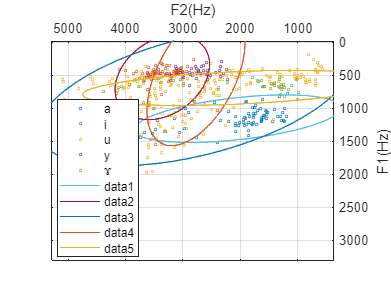

cEllipse = zeros(n,2);
aEllipse = zeros(n,1);
bEllipse = zeros(n,1);
phiEllipse = zeros(n,1);

thetaGrid = linspace(0,2*pi);
figure(figAll);
plotXMin = min(pt{1}(:,2));
plotXMax = max(pt{1}(:,2));
plotYMin = min(pt{1}(:,1));
plotYMax = max(pt{1}(:,1));

for k = 1:n
    plotXMin = min(min(pt{k}(:,2)),plotXMin);
    plotXMax = max(max(pt{k}(:,2)),plotXMax);
    plotYMin = min(min(pt{k}(:,1)),plotYMin);
    plotYMax = max(max(pt{k}(:,1)),plotYMax);
    [cEllipse(k,:),aEllipse(k),bEllipse(k),phiEllipse(k)]...
        = getEllipseChi(pt{k}(:,2),pt{k}(:,1));
    R = [cos(phiEllipse(k)),sin(phiEllipse(k));...
        -sin(phiEllipse(k)),cos(phiEllipse(k))];
    rEllipse = [aEllipse(k)*cos(thetaGrid);bEllipse(k)*sin(thetaGrid)]' * R;

    plot(rEllipse(:,1) + cEllipse(k,1),rEllipse(:,2) + cEllipse(k,2),'-');
    hold on;
end
axis([plotXMin-200,plotXMax+200,plotYMin-200,plotYMax+200]);

## 计算包含95%散点的椭圆函数

% 计算包含95%散点的椭圆函数（散点符合卡方分布/高斯分布）

function [center,a,b,phi] = getEllipseChi(x,y)
% x & y: n by 1 vectors

data = [x,y];
covariance = cov(data);
[eigVec, eigVal] = eig(covariance);

% Get the index of the largest eigenvector
[eigVecMaxInd, ~] = find(eigVal == max(eigVal,[],'all'));
eigVecMax = eigVec(:, eigVecMaxInd);

% Get the largest eigenvalue
eigValMax = max(eigVal,[],'all');

% Get the smallest eigenvector and eigenvalue
if(eigVecMaxInd == 1)
    eigValMin = max(eigVal(:,2));
    eigVecMin = eigVec(:,2);
else
    eigValMin = max(eigVal(:,1));
    eigVecMin = eigVec(1,:);
end

% Calculate the angle between the x-axis and the largest eigenvector
angle = atan2(eigVecMax(2), eigVecMax(1));

% This angle is between -pi and pi.
% Let's shift it such that the angle is between 0 and 2pi
if(angle < 0)
    angle = angle + 2*pi;
end

% Get the coordinates of the data mean
center = mean(data);

% Get the 95% confidence interval error ellipse (Chi-square distribution)
chisquare_val = 2.4477;
phi = angle;
a = chisquare_val*sqrt(eigValMax);
b = chisquare_val*sqrt(eigValMin);
end


% 计算包含95%散点的椭圆函数

function [center,a,b,phi] = getEllipse(x,y)
% x & y: n by 1 vectors
data = [x,y];




end
